## Plot Path

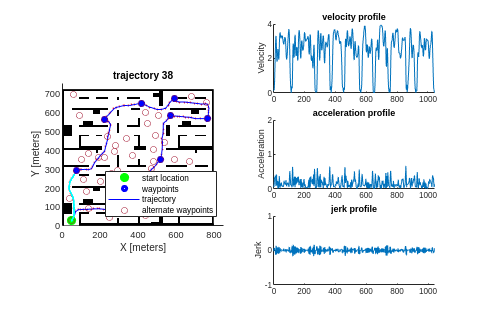

load bigmap.mat;

% f1 = figure(1); clf;
% f1.Position = [1 1 1000 600];
% subplot(2,2, [1; 3]);
% 
% hold on;
% show(map);
% scatter(trajectory.x_ref_points(:,2), trajectory.y_ref_points(:,2), 3, 'm', 'filled', "DisplayName", "reference");
% plot(trajectory.destination(1), trajectory.destination(2), 'rx', 'markerfacecolor', 'r', 'LineWidth', 5, 'markersize', 15, "DisplayName", "destination");
% 
% plot(position.gps.Data(1,1), position.gps.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8, "DisplayName", "start");
% for i = 1:length(trajectory.waypoints(:,1))
%    plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'bo', 'LineWidth', 3, "DisplayName", "waypoint"); 
% end
% %plot(pos_actual.Data(:,1), pos_actual.Data(:,2), 'linewidth', 6);
% plot(position.true.Data(:,1), position.true.Data(:,2), 'c', 'linewidth', 2, "DisplayName", "actual");
% if ~any(stop_codes.Data(:,find(strcmp(stop_code_tb.description, 'success'))))
%     plot(position.gps.Data(end, 1), position.gps.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3, "DisplayName", "crash");
% end
% if any(stop_codes.Data(:,find(strcmp(stop_code_tb.description, 'success'))))
%     plot(position.gps.Data(end, 1), position.gps.Data(end, 2), 'g^', 'markersize', 14, 'LineWidth', 3, "DisplayName", "success");
% end
% % fault_pos = getsampleusingtime(position.gps, 180).Data(1:2);
% % plot(fault_pos(1), fault_pos(2), 'kx', 'markersize', 15, 'LineWidth', 3, 'DisplayName', 'Fault Occured');
% % fault_pos = getsampleusingtime(position.gps, 191).Data(1:2);
% % plot(fault_pos(1), fault_pos(2), 'gx', 'markersize', 9, 'LineWidth', 3, 'DisplayName', 'Fault Detected');
% hold off;
% %axis([0 100 0 100])
% title("UAV Path and Waypoints");
% 
% vel = sqrt(velocity.gps.Data(:,1).^2 + velocity.gps.Data(:,2).^2);
% acc = sqrt(acceleration.Data(:,1).^2 + acceleration.Data(:,2).^2);
% 
% subplot(2,2,2);
% title("velocity profile")
% hold on;
% plot(trajectory.velocity_profile(3,:), 'linewidth', 2, 'displayname', 'velocity profile');
% plot(velocity.gps.Time, vel, 'displayname', 'velocity actual');
% hold off;
% ylabel('Velocity');
% legend(Location='southeast');
% 
% subplot(2,2,4);
% title("acceleration profile")
% hold on;
% plot(trajectory.acceleration_profile(3,:), 'linewidth', 2, 'displayname', 'acceleration profile');
% plot(acceleration.Time, acc,'displayname', 'acceleration actual');
% hold off;
% ylabel('Acceleration');
% 





f1 = figure(1); clf;
f1.Position = [1 1 1000 600];
subplot(3,2, [1; 3; 5]);

hold on;
show(map);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
% for i = 2:length(trajectory.waypoints(:,1))-1
% %for i = 1:length(trajectory.x_waypoints)
%  %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
%    t = plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'bo', 'Markersize', 15, 'LineWidth', 2, 'DisplayName', sprintf("p%d", i)); 
% end
plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
h = plot(trajectory.start(1), trajectory.start(2), 'go', 'color', 'green', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 2:length(trajectory.waypoints(:,1))-1
  t= plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'bo', 'Markersize', 4, 'LineWidth', 3); 
end
for i = 2:length(trajectory.path)-1
   b = plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
end
%text(trajectory.waypoints(:,1)-5, trajectory.waypoints(:,2), string(1:numel(trajectory.waypoints(:,1))));
%plot(current_location(1), current_location(2), 'x', 'MarkerFaceColor', 'red', 'markersize', 17, 'LineWidth', 5, 'DisplayName', sprintf("p%d", i)); 
axis([0 850 0 750])
s = scatter(all_waypoints(:,1), all_waypoints(:,2));

plot(position.true.Data(:,1), position.true.Data(:,2), 'c', 'linewidth', 2, "DisplayName", "actual");
if ~any(stop_codes.Data(:,find(strcmp(stop_code_tb.description, 'success'))))
    plot(position.gps.Data(end, 1), position.gps.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3, "DisplayName", "crash");
end
if any(stop_codes.Data(:,find(strcmp(stop_code_tb.description, 'success'))))
    plot(position.gps.Data(end, 1), position.gps.Data(end, 2), 'g^', 'markersize', 14, 'LineWidth', 3, "DisplayName", "success");
end

title(sprintf("trajectory %d", trajectory.id));
legend([h(1), t(1), b(1), s(1)], 'start location', 'waypoints', 'trajectory', 'alternate waypoints', 'location', 'se');
hold off;

vel = sqrt(velocity.gps.Data(:,1).^2 + velocity.gps.Data(:,2).^2);
acc = sqrt(acceleration.Data(:,1).^2 + acceleration.Data(:,2).^2);


subplot(3,2,2);
title("velocity profile")
hold on;
plot(trajectory.velocity_profile(3,:));
%plot(velocity.gps.Time, vel, 'displayname', 'velocity actual');
ylabel('Velocity');
hold off;

subplot(3,2,4);
hold on;
title("acceleration profile")
plot(trajectory.acceleration_profile(3,:));
%plot(acceleration.Time, acc,'displayname', 'acceleration actual');
ylim([0 2]);
ylabel('Acceleration');
hold off;

subplot(3,2,6);
hold on;
title("jerk profile")
plot(diff(trajectory.acceleration_profile(3,:)));
%plot(acceleration.Time(1:end-1), diff(acc),'displayname', 'jerk actual');
ylim([-1 1]);
ylabel('Jerk');
hold off;

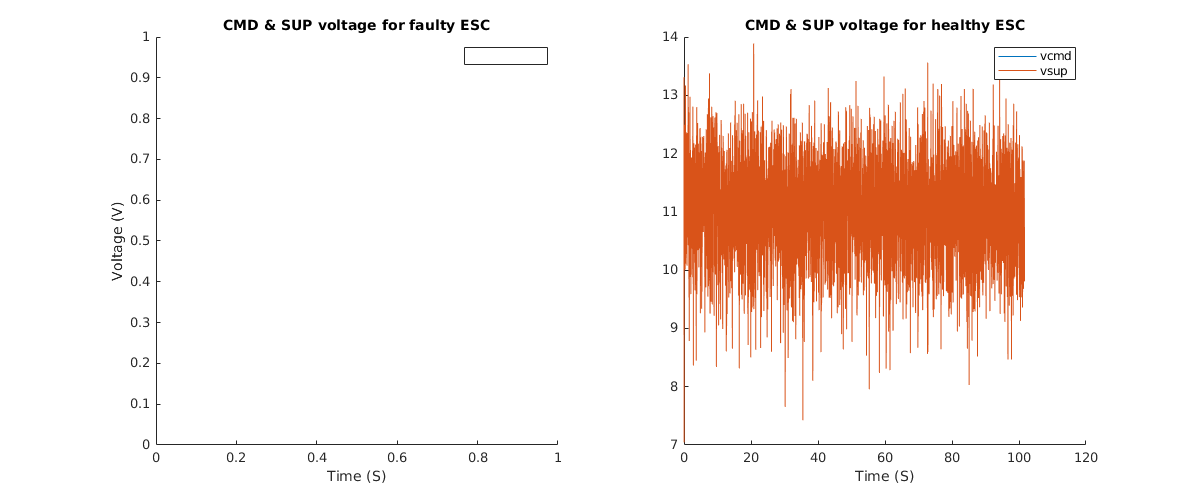
















% subplot(1,2,2);
% hold on;
% vel = sqrt(velocity.gps.Data(:,1).^2 + velocity.gps.Data(:,2).^2);
% acc = sqrt(acceleration.Data(:,1).^2 + acceleration.Data(:,2).^2);
% plot(velocity.gps.Time, vel, 'linewidth', 2, 'displayname', 'velocity (L)');
% plot(acceleration.Time, acc, 'linewidth', 2, 'displayname', 'acceleration');
% % yyaxis right;
% % plot(position.true.Time, position.true.Data(:,1), 'm-', 'displayname', 'xpos (R)');
% % plot(position.true.Time, position.true.Data(:,2), 'g-', 'displayname', 'ypos (R)');
% % yline(trajectory.destination(1), 'm--', 'displayname', 'xref');
% % yline(trajectory.destination(2), 'g--', 'displayname', 'yref');
% %plot(errors.euclidean_pos_err.Time, errors.euclidean_pos_err.Data, 'linewidth', 2, 'DisplayName', 'pos err');
% hold off;
%ylim([0 55]);
%legend(Location='southeast');
f9 = figure(9); clf;
f9.Position = [0 0 1200 500];
subplot(1,2,1);
hold on;
try
    idx = find(any(escs.esc_faults.Data), 1);
if any(idx)
    plot(escs.vcmd.Time, escs.vcmd.Data(:,idx), 'displayname', 'vcmd');
    plot(escs.vcmd.Time, escs.vsup.Data(:,idx), 'displayname', 'vsup');
end
catch e
    disp(e)
end
hold off;

legend;
title('CMD & SUP voltage for faulty ESC')
ylabel('Voltage (V)');
xlabel('Time (S)');

try
    subplot(1,2,2);
    hold on;
    idx = find(~any(escs.esc_faults.Data), 1);
    plot(escs.vcmd.Time, escs.vcmd.Data(:,idx), 'displayname', 'vcmd');
    plot(escs.vcmd.Time, escs.vsup.Data(:,idx), 'displayname', 'vsup');
    hold off;
    title('CMD & SUP voltage for healthy ESC')
    xlabel('Time (S)');
    legend;
catch e
    disp(e);
end

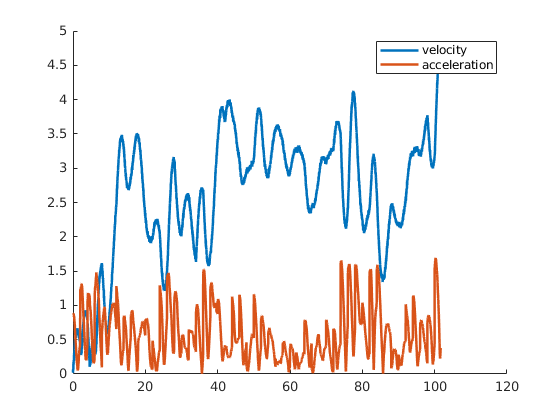



f10 = figure(10); clf;
hold on;
vel = sqrt(velocity.gps.Data(:,1).^2 + velocity.gps.Data(:,2).^2);
acc = sqrt(acceleration.Data(:,1).^2 + acceleration.Data(:,2).^2);
plot(velocity.gps.Time, vel, 'linewidth', 2, 'displayname', 'velocity');
plot(acceleration.Time, acc, 'linewidth', 2, 'displayname', 'acceleration');
%yyaxis right;
%plot(errors.euclidean_pos_err.Time, errors.euclidean_pos_err.Data, 'linewidth', 2, 'DisplayName', 'pos err');
hold off;
legend;

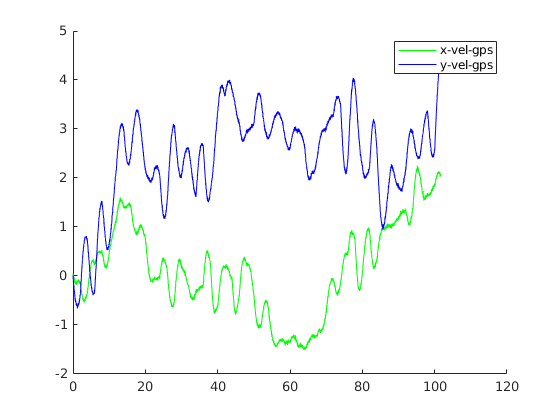

f11 = figure(11); clf;
hold on;
plot(velocity.gps.Time, velocity.gps.Data(:,1), 'g-', 'displayname', 'x-vel-gps');
plot(velocity.gps.Time, velocity.gps.Data(:,2), 'b-', 'displayname', 'y-vel-gps');


hold off;
legend;

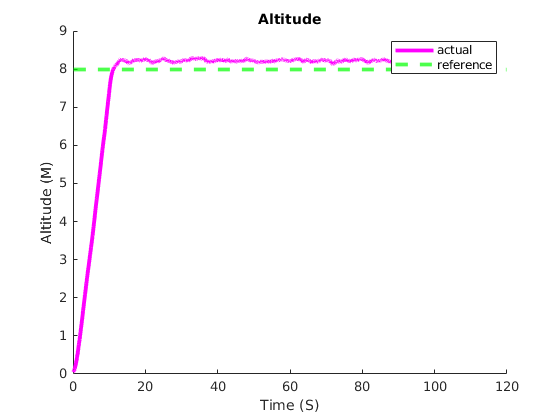

f6 = figure(6); clf;
hold on;
plot(position.true.Time, position.true.Data(:,3), 'm', 'linewidth', 3, "DisplayName", "actual");
yline(sim_params.z_ref, 'g--', 'linewidth', 3, 'DisplayName', 'reference');
hold off;
legend;
title("Altitude");
xlabel('Time (S)');
ylabel('Altitude (M)');

## Euclidean Position Error

avgposerr = mean(errors.euclidean_pos_err.Data)

avgposerr = 2.1160

varposerr = var(errors.euclidean_pos_err.Data)

varposerr = 0.5665

mean(errors.var_pos_err.Data)

ans = 0.1882

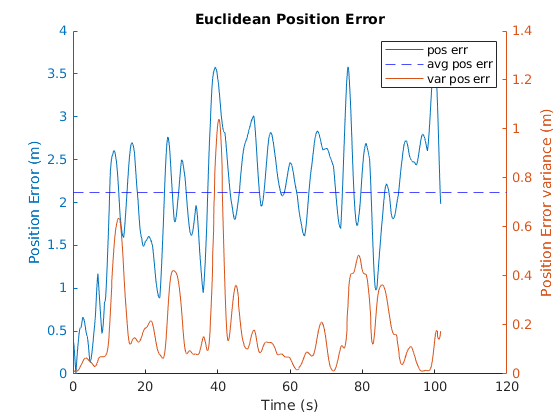

f8 = figure(8); clf;
hold on;
yyaxis left;
%ylim([0 3.5]);
plot(errors.euclidean_pos_err.Time, errors.euclidean_pos_err.Data, 'DisplayName', 'pos err');
yline(avgposerr, 'b--', 'DisplayName', 'avg pos err');
ylabel("Position Error (m)");
yyaxis right;
%ylim([0 3.5]);
plot(errors.var_pos_err.Time, errors.var_pos_err.Data, 'DisplayName', 'var pos err')
hold off;
legend;
title('Euclidean Position Error');
xlabel("Time (s)");
ylabel("Position Error variance (m)");

## Voltage and SOC Plot

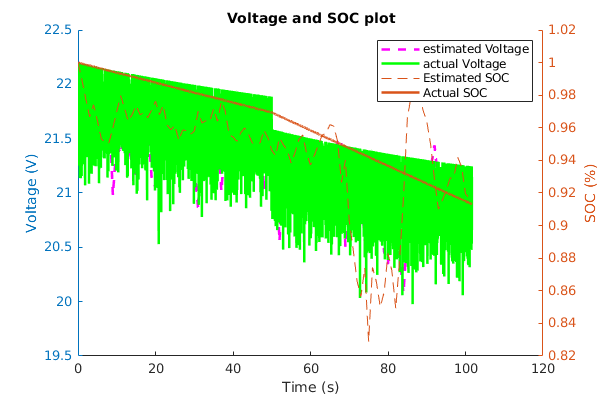

f3 = figure(3); clf;
f3.Position = [0 0 600 400];
yyaxis left;
hold on;
try
    plot(battery.battery_hat.v.Time(:), battery.battery_hat.v.Data(:,1), 'm--', 'linewidth', 2, "DisplayName", "estimated Voltage");
catch e
    disp(e);
end
    plot(battery.battery_true.v.Time(:), battery.battery_true.v.Data(:,1), 'g-', 'linewidth', 2, "DisplayName", "actual Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;

try
    plot(battery.battery_hat.z.Time(:), battery.battery_hat.z.Data(:), '--', "DisplayName", "Estimated SOC");
catch e
    disp(e);
end

plot(battery.battery_true.z.Time(:), battery.battery_true.z.Data(:),'-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
title('Voltage and SOC plot');
xlabel("Time (s)");
ylabel("SOC (%)");
%xlim([500 550]);
legend();

## Current Plot

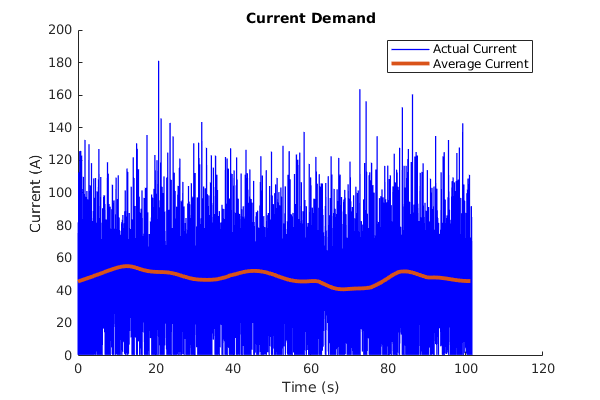

f4 = figure(4); clf;
f4.Position = [0 0 600 400];
hold on;
plot(battery.battery_true.i.Time(:), battery.battery_true.i.Data(:), 'b', 'linewidth', 1, "DisplayName", "Actual Current");
plot(downsample(battery.battery_true.i.Time(:), 20),smoothdata(downsample(battery.battery_true.i.Data(:), 20), 'rlowess', 50), 'linewidth', 3, "DisplayName", "Average Current");
hold off;
title('Current Demand');
xlabel("Time (s)");
ylabel("Current (A)");
legend();